clc
clearvars
close all

nlist = readtable("./data/nlist.csv");
nlist.Properties.VariableNames = {'Name','Label','Group'};
nlist.Name = string(nlist.Name);
elist_dy = readtable("./data/elist_dynamic.csv");

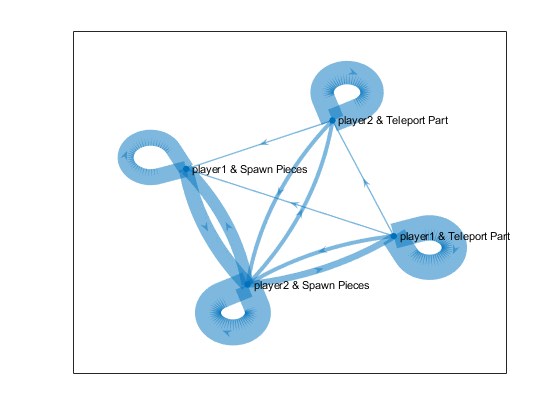

num_edges = size(elist_dy,1);
snodes = elist_dy.Source;
tnodes = elist_dy.Target;
edge_weight_cutoff = 16;

s = snodes(1);
t = tnodes(1);
elist = [s,t];
w = 1;
etable = table(elist,w, 'VariableNames',{'EndNodes','Weight'});
G = digraph(etable);

for i=2:num_edges
    s = snodes(i);
    t = tnodes(i);
    [edge_exist,update_idx] = ismember([s,t],G.Edges.EndNodes,'rows');

    if(all(edge_exist))
        w = G.Edges.Weight;
        if(w(update_idx) >= edge_weight_cutoff)
            G.Edges.Weight(update_idx) = w(update_idx) + (0.5)^(w(update_idx)-edge_weight_cutoff+1);
        else
            G.Edges.Weight(update_idx) = w(update_idx)+1;
        end
    else
        G = addedge(G,s,t,1);
    end
    plot(G,'NodeLabel',nlist.Label,'LineWidth',G.Edges.Weight)
    drawnow
end